Polar Plots

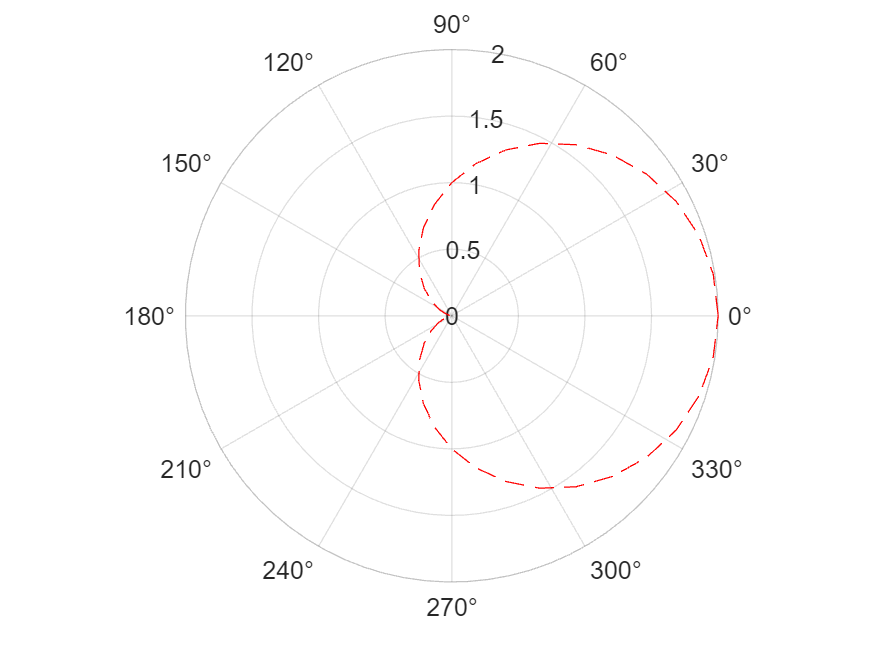

g = 0.5;
theta = linspace(0,2*pi,41);
G = 2*g*(1+cos(theta));

polarplot(theta, G, 'r--')

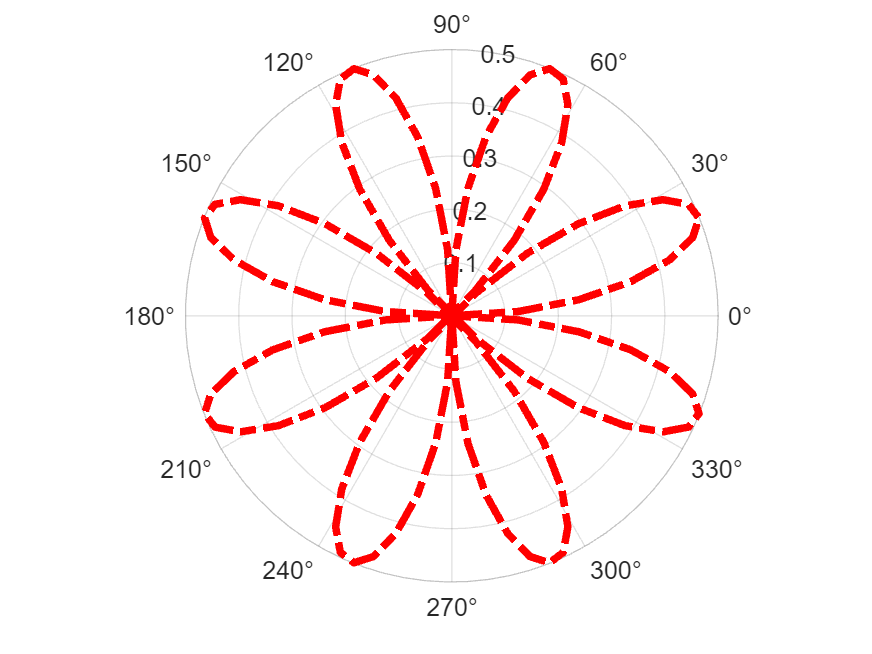

theta = linspace(0,2*pi,101);
rho = sin(2*theta).*cos(2*theta);

polarplot(theta, rho, 'Color','r', 'LineStyle','-.', 'LineWidth',3)

theta = pi/4:pi/4:2*pi

theta =     0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978    6.2832


rho = [19 6 12 18 16 11 15 15]

rho =     19     6    12    18    16    11    15    15


sz = [150 250 20 50 100 200 500 1000]

sz =          150         250          20          50         100         200         500        1000


%doc polarscatter
c = [1 2 3 5 10 12 3 4]

c =      1     2     3     5    10    12     3     4


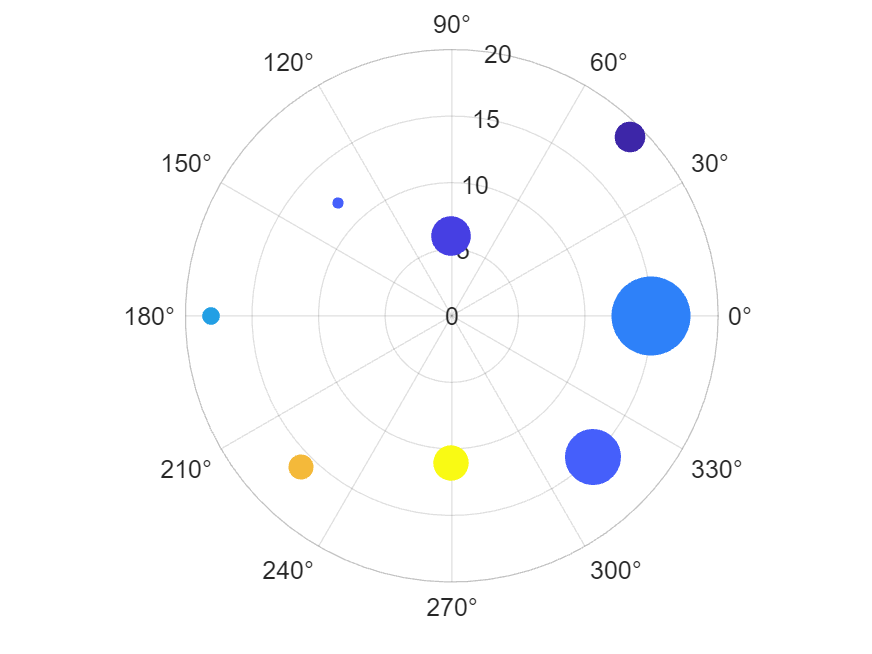


polarscatter(theta,rho,sz,c,'filled')

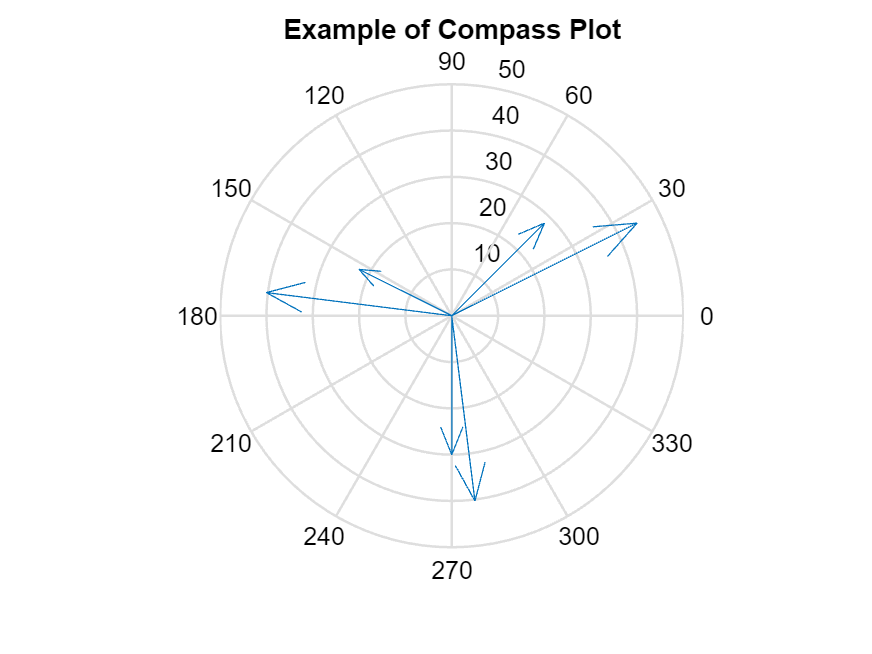

%doc compass

x = [20 5 -40 -20 0 40];
y = [20 -40 5 10 -30 20];
compass(x,y)
title('Example of Compass Plot')

Discrete Data Plots

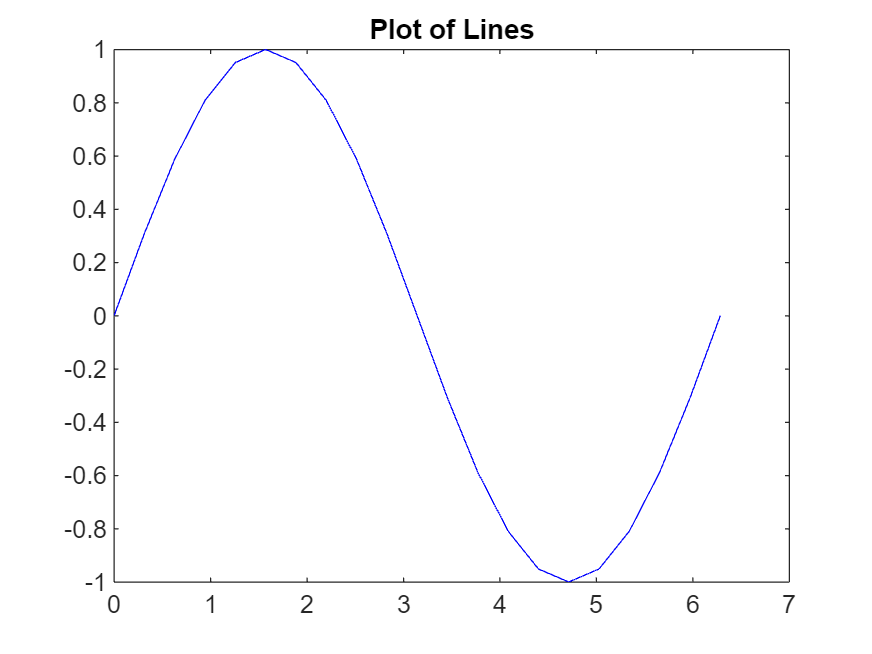

x = linspace(0,2*pi,21);
y = sin(x);

plot(x,y,'b-')
title('Plot of Lines')

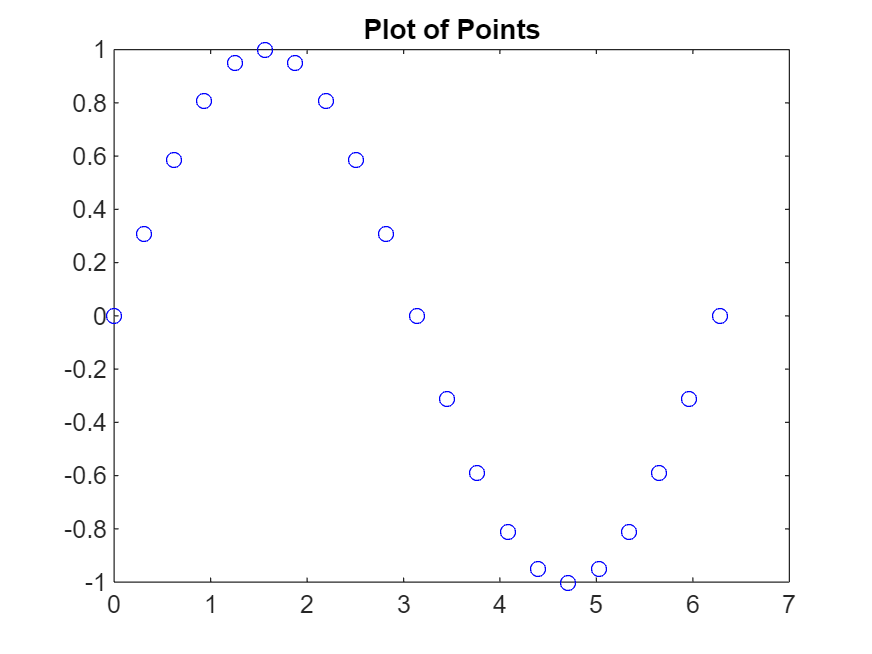


plot(x,y,'bo')
title('Plot of Points')

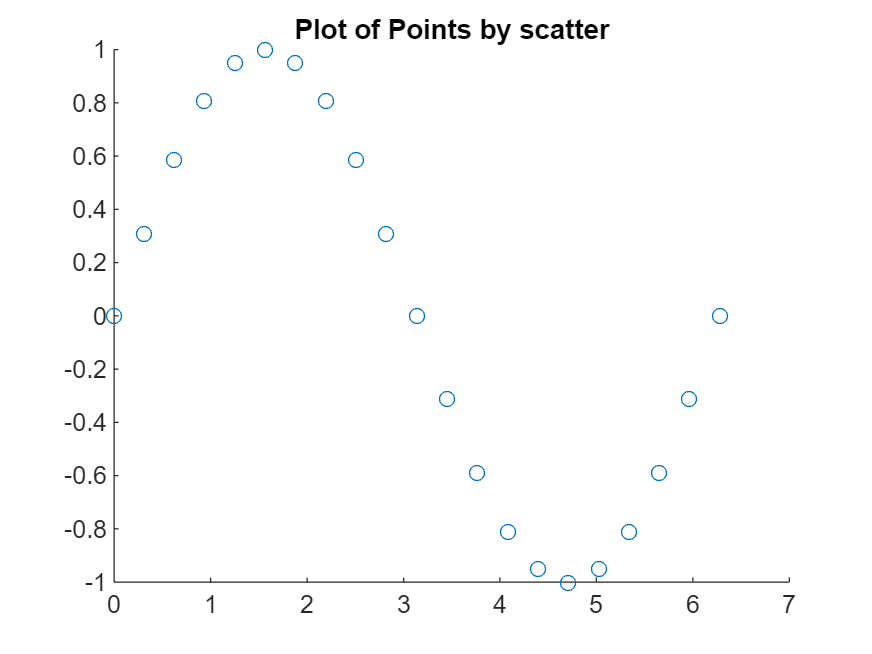


scatter(x,y)
title('Plot of Points by scatter')

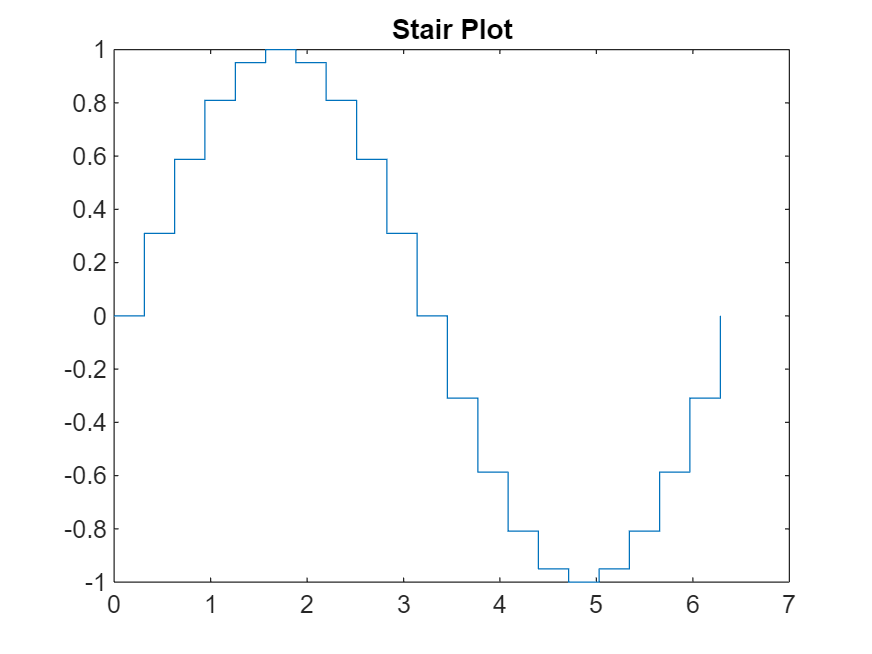


stairs(x,y)
title('Stair Plot')

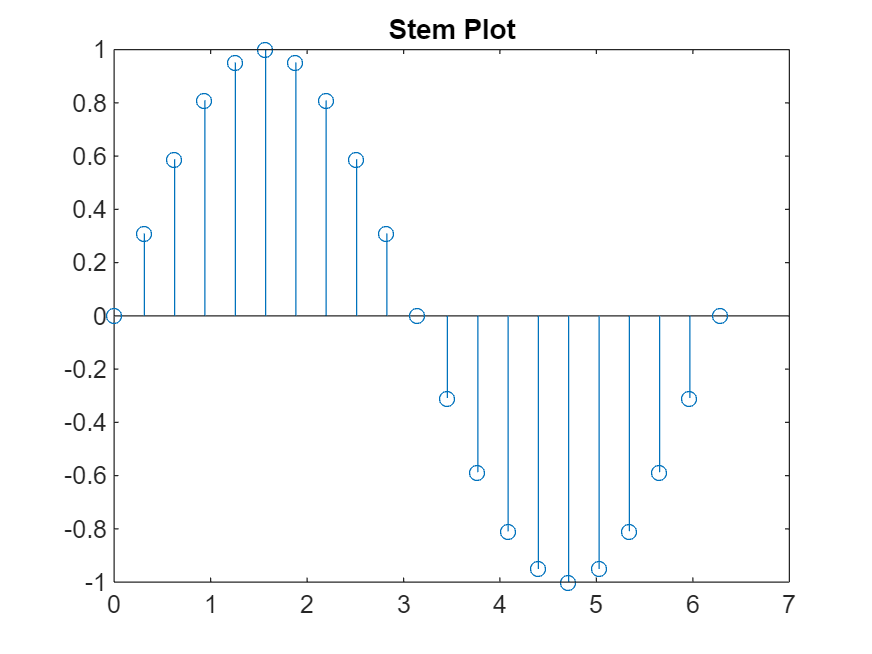


stem(x,y)
title('Stem Plot')

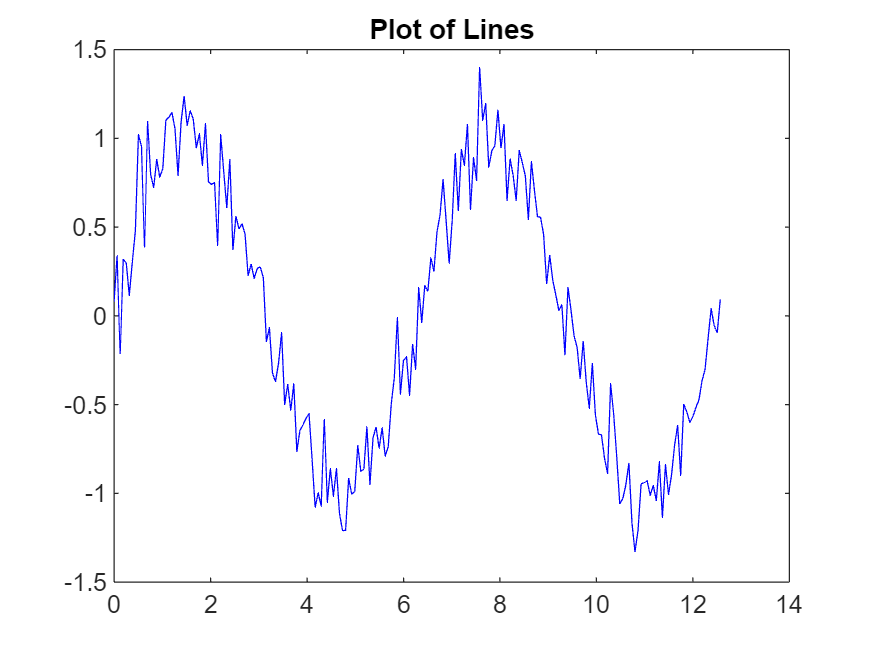

x = linspace(0,4*pi,200);
y = sin(x)+0.15*randn(size(x));

plot(x,y,'b-')
title('Plot of Lines')

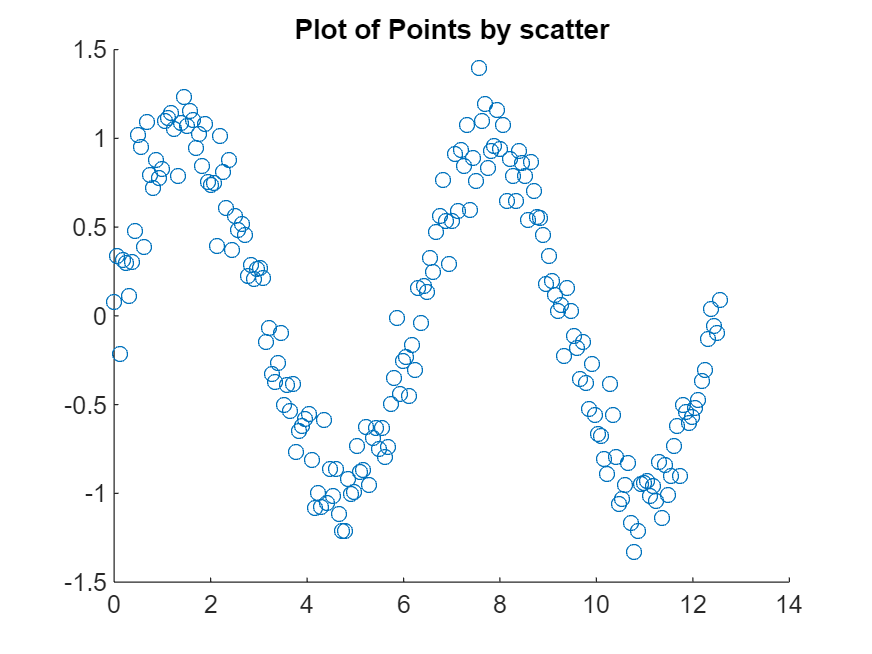


scatter(x,y)
title('Plot of Points by scatter')

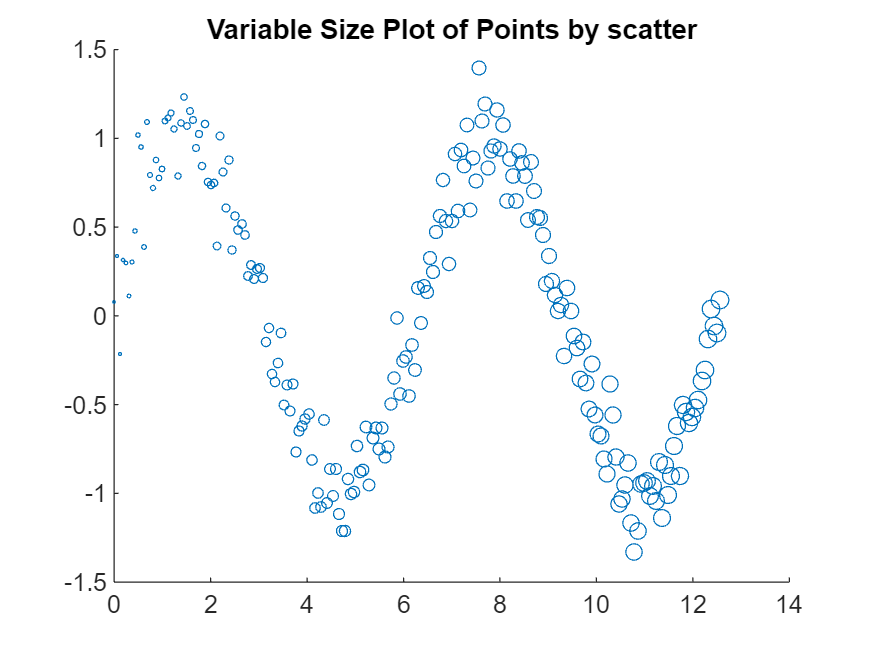


sz = linspace(1,50,200);
scatter(x,y,sz)
title('Variable Size Plot of Points by scatter')

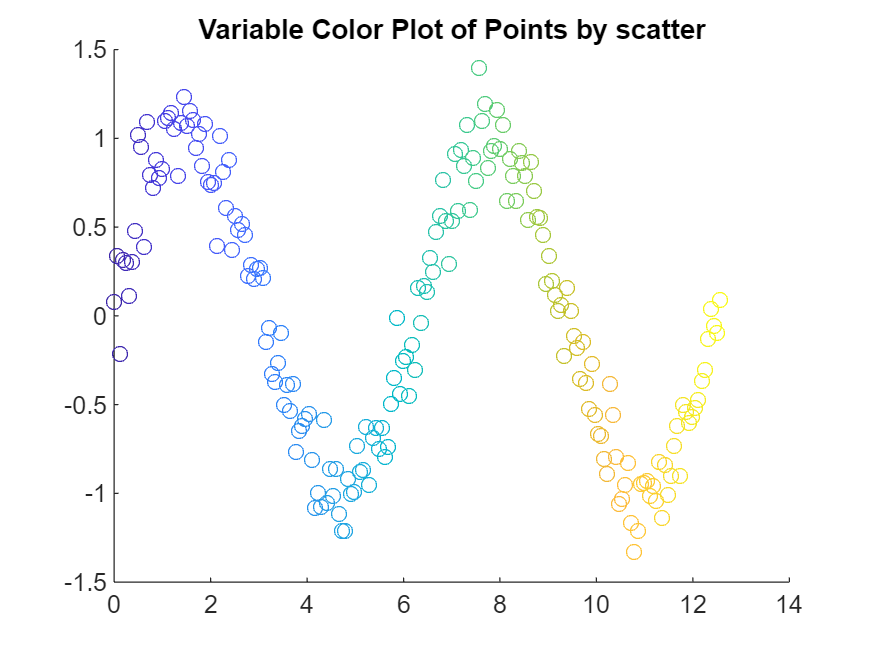


c = linspace(1,50,200);
scatter(x,y,[],c)
title('Variable Color Plot of Points by scatter')

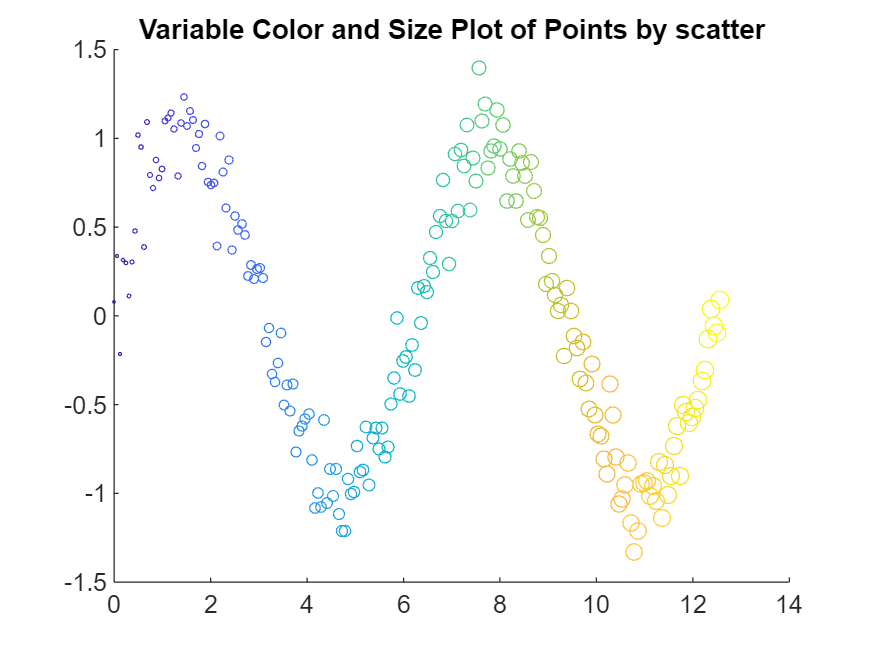


c = linspace(1,50,200);
scatter(x,y,sz,c)
title('Variable Color and Size Plot of Points by scatter')

Pie Charts

%doc pie

data = [10 37 5 6 6]

data =     10    37     5     6     6


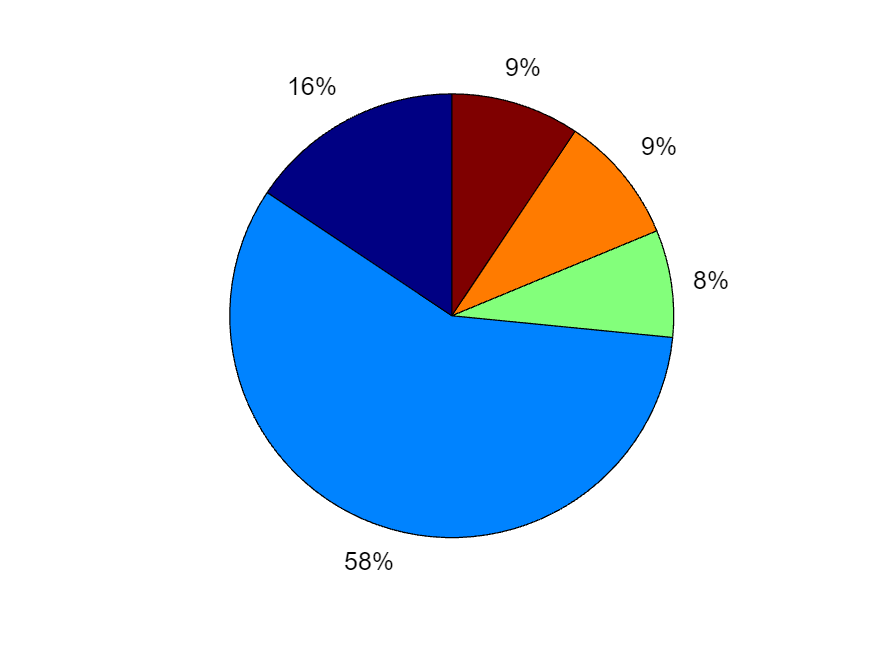

pie(data)
%doc colormap
colormap('gray')
colormap jet

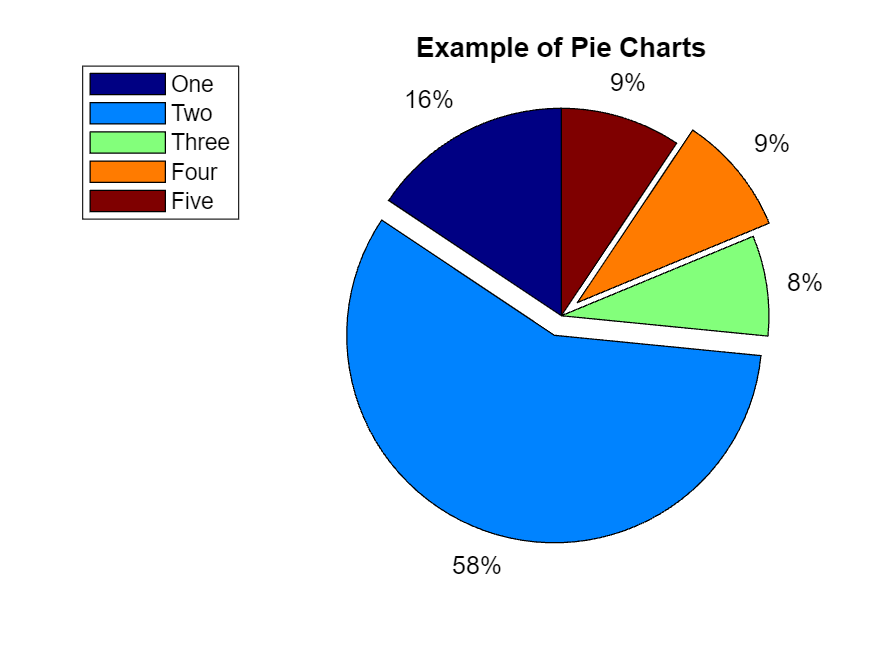


e = [0 1 0 1 0];
pie(data, e)
title('Example of Pie Charts')
legend('One','Two', 'Three', 'Four', 'Five','Location','northwestoutside')

Bar Plots

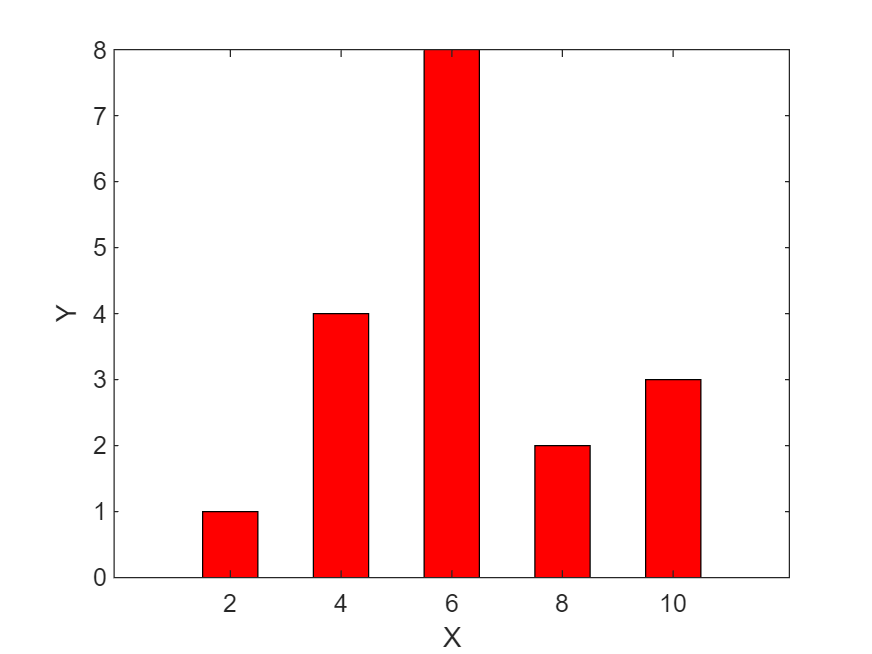

%doc bar
x = [2 4 6 8 10];
y = [1 4 8 2 3];

bar(x,y,0.5,'r')
xlabel('X')
ylabel('Y')


y = [1 4 8 2 3; 2 1 2 8 3; 1 3 6 1 2]

y =      1     4     8     2     3
     2     1     2     8     3
     1     3     6     1     2


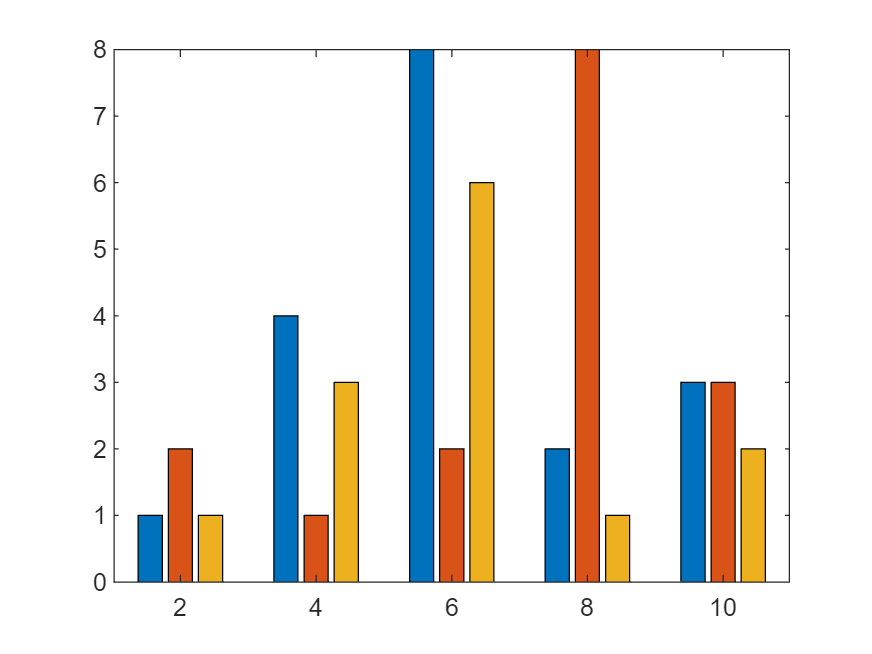

bar(x,y)

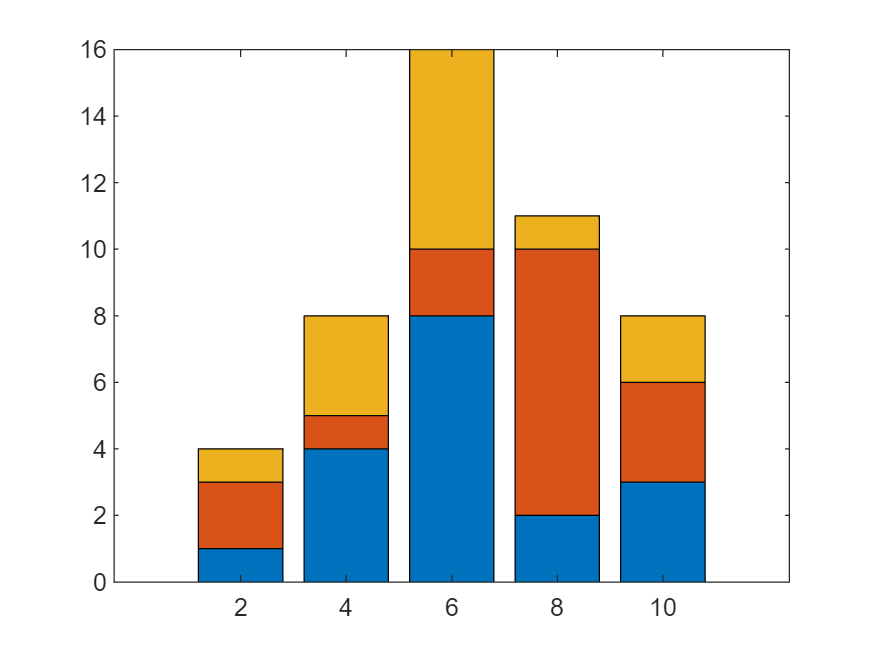

bar(x,y,'stacked')

Histogram Charts

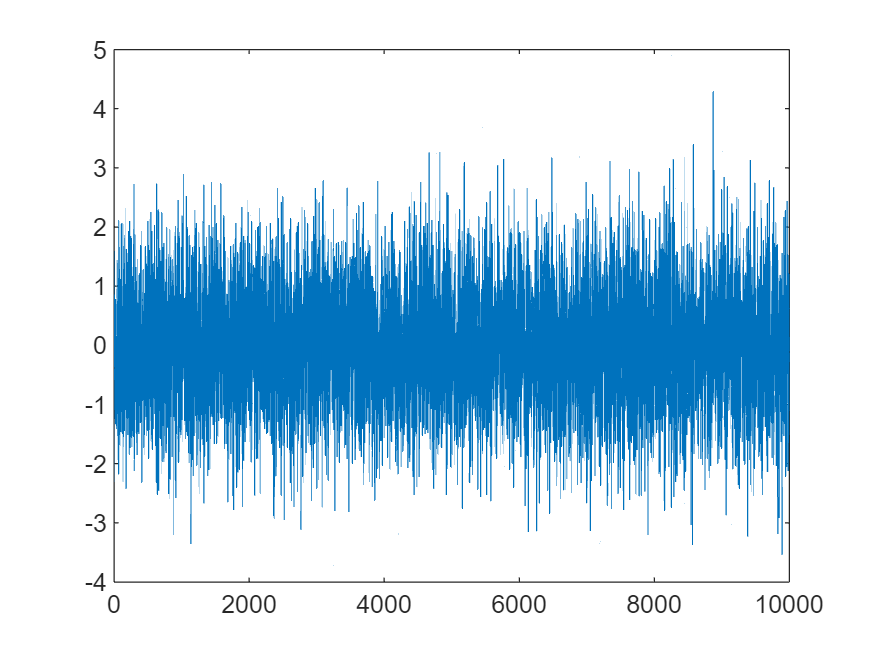

%doc histogram

y = randn(10000,1);

plot(y)

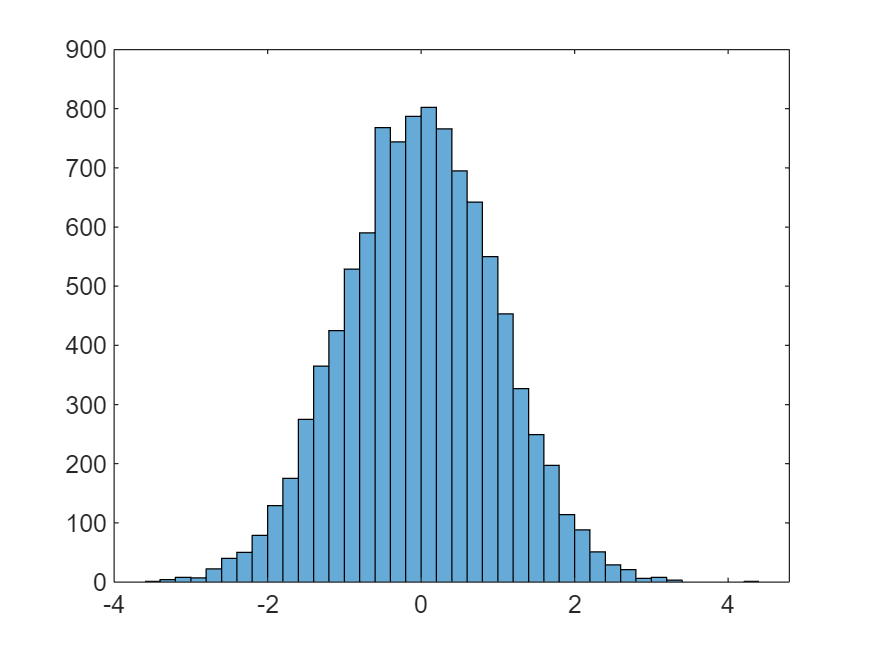

histogram(y)

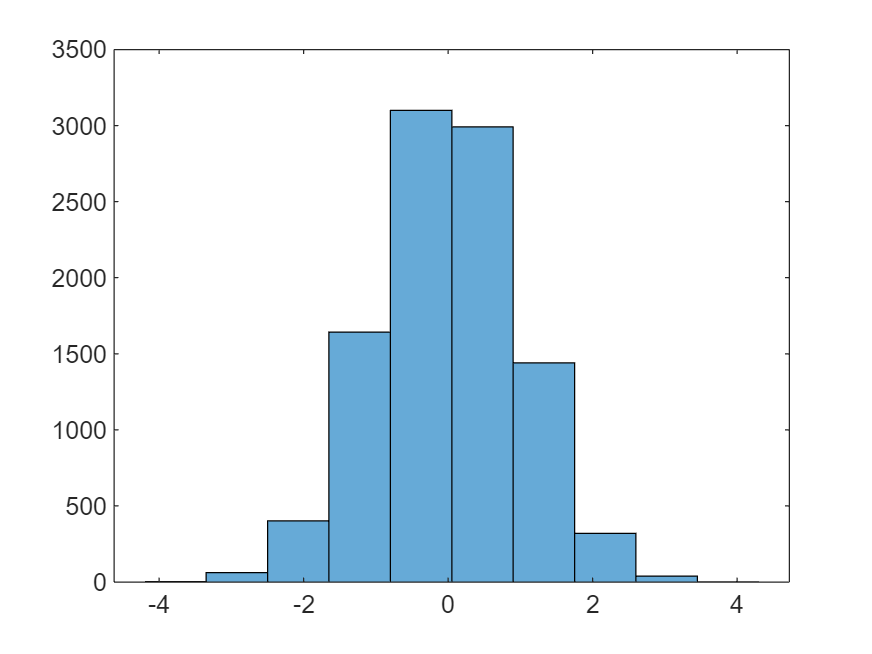

histogram(y,10)

counst =   Histogram with properties:

             Data: [10000×1 double]
           Values: [1 4 8 7 22 40 50 79 129 175 275 365 425 529 590 768 744 787 802 766 695 642 550 453 327 249 197 114 88 51 29 21 6 8 3 0 0 0 0 1]
          NumBins: 40
         BinEdges: [-3.6000 -3.4000 -3.2000 -3 -2.8000 -2.6000 -2.4000 -2.2000 -2 -1.8000 -1.6000 -1.4000 -1.2000 -1 -0.8000 -0.6000 -0.4000 -0.2000 0 0.2000 0.4000 0.6000 0.8000 1.0000 1.2000 1.4000 1.6000 1.8000 2.0000 2.2000 2.4000 2.6000 2.8000 … ]
         BinWidth: 0.2000
        BinLimits: [-3.6000 4.4000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


counst = histogram(y)

2D Histogram Charts

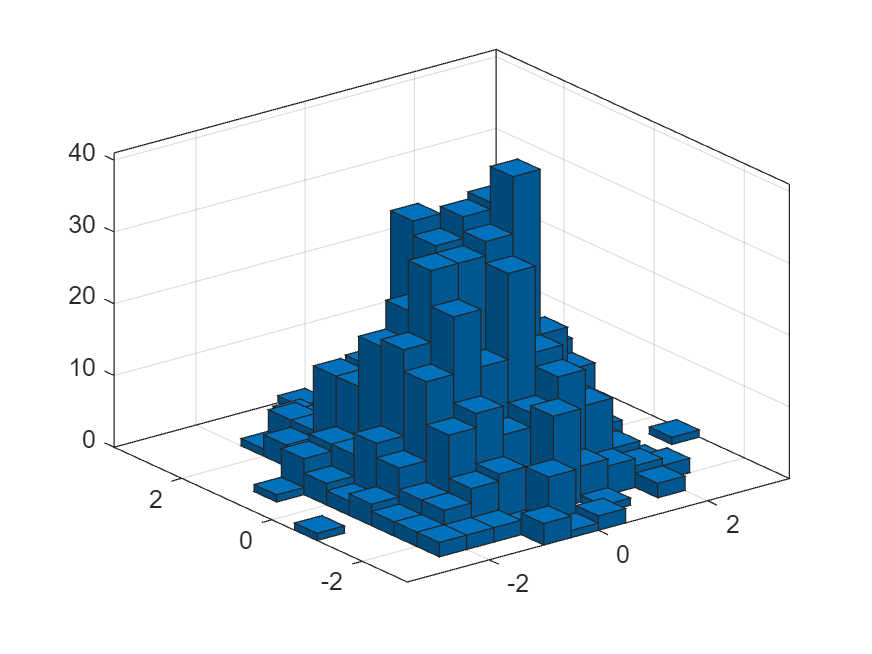


X = randn(1000,1);
Y = randn(1000,1);

histogram2(X,Y)

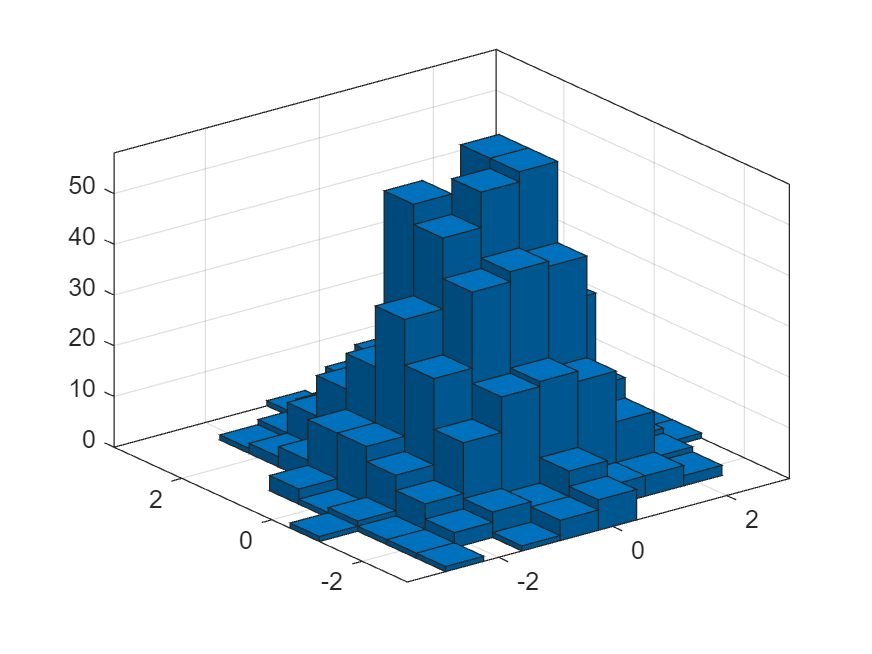


histogram2(X,Y,10)

counst =   Histogram2 with properties:

             Data: [1000×2 double]
           Values: [10×10 double]
          NumBins: [10 10]
        XBinEdges: [-3.6000 -2.9300 -2.2600 -1.5900 -0.9200 -0.2500 0.4200 1.0900 1.7600 2.4300 3.1000]
        YBinEdges: [-3.0000 -2.3500 -1.7000 -1.0500 -0.4000 0.2500 0.9000 1.5500 2.2000 2.8500 3.5000]
         BinWidth: [0.6700 0.6500]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0.1500 0.1500 0.1500]

  Show all properties

counst = histogram2(X,Y,10)


counst.Values

ans =      0     0     0     1     0     0     0     0     0     0
     1     1     1     2     1     3     0     0     0     0
     0     3     6     9    12    12     4     2     1     0
     1     5    16    26    35    23    16     8     2     0
     4     4    23    41    49    53    20    13     4     1
     6     9    24    43    56    44    38    14     3     0
     0     4    22    42    58    58    26    12     1     1
     0     4    12    16    30    24    12     5     1     0
     0     2     3     4     5     7     2     3     1     0
     0     0     0     1     1     1     0     1     1     0


Area Function

x = 0:pi/20:4*pi;
y = sin(x)

y =          0    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000   -0.9877   -0.9511   -0.8910   -0.8090   -0.7071   -0.5878   -0.4540   -0.3090   -0.1564   -0.0000    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877


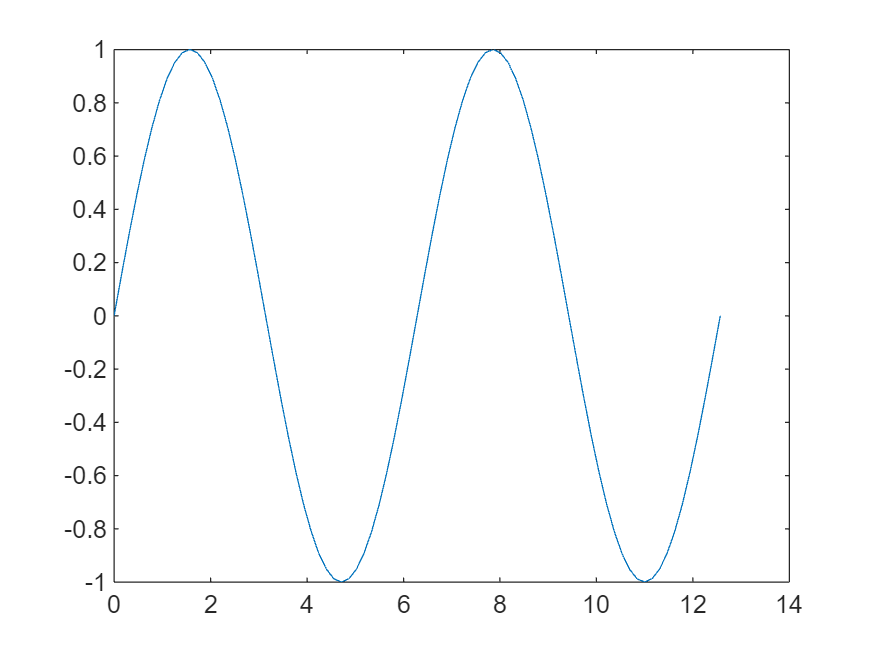

plot(x,y)

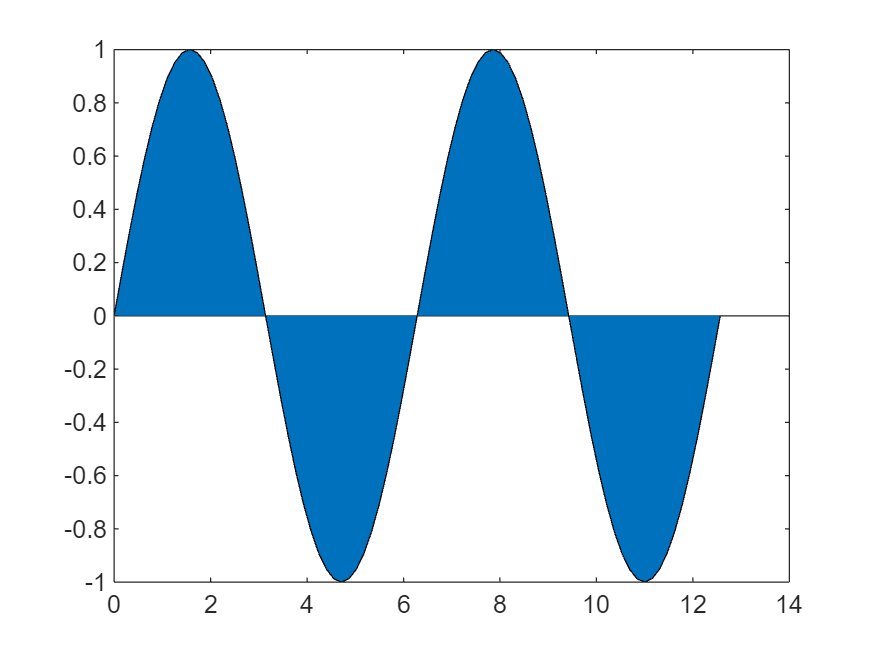

area(x,y)

Line Plots (3D)

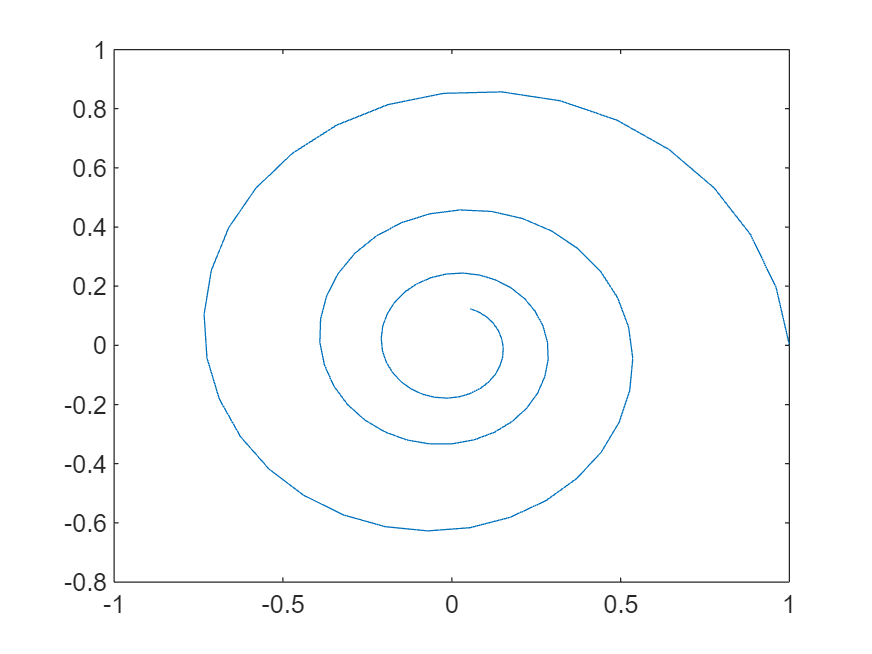

t = 0:0.1:10;

x = exp(-0.2*t).*cos(2*t);
y = exp(-0.2*t).*sin(2*t);

plot(x,y)

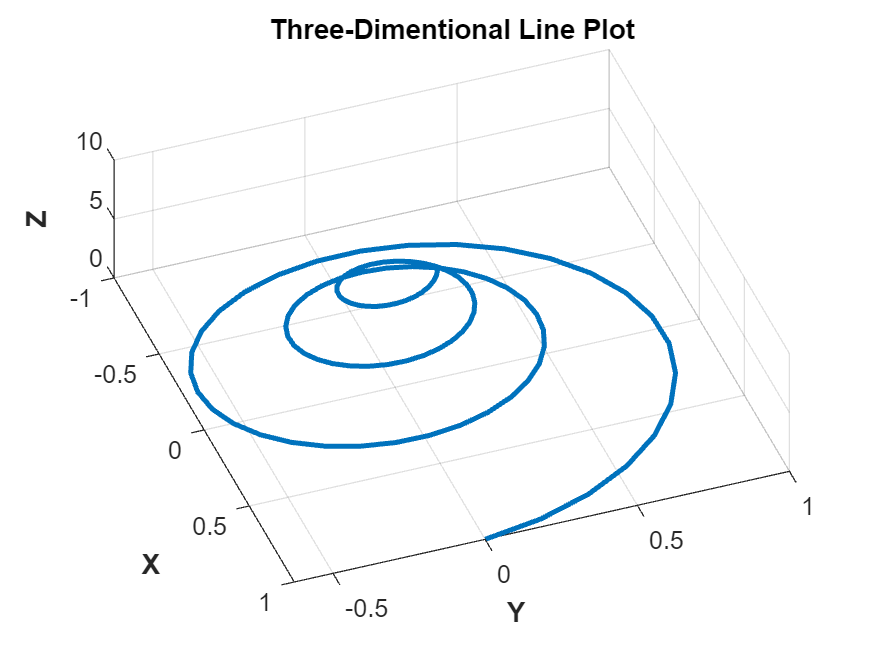

plot3(x,y,t,'LineWidth',2)
title('Three-Dimentional Line Plot')
grid on
xlabel('\bfX')
ylabel('\bfY')
zlabel('\bfZ')

%view([-49.07 60.15])
%doc view

view(2)
view(3)
view(70,70)

Stem3

t = 0:pi/30:2*pi;
x = cos(t)

x =     1.0000    0.9945    0.9781    0.9511    0.9135    0.8660    0.8090    0.7431    0.6691    0.5878    0.5000    0.4067    0.3090    0.2079    0.1045    0.0000   -0.1045   -0.2079   -0.3090   -0.4067   -0.5000   -0.5878   -0.6691   -0.7431   -0.8090   -0.8660   -0.9135   -0.9511   -0.9781   -0.9945   -1.0000   -0.9945   -0.9781   -0.9511   -0.9135   -0.8660   -0.8090   -0.7431   -0.6691   -0.5878   -0.5000   -0.4067   -0.3090   -0.2079   -0.1045   -0.0000    0.1045    0.2079    0.3090    0.4067


y = sin(t)

y =          0    0.1045    0.2079    0.3090    0.4067    0.5000    0.5878    0.6691    0.7431    0.8090    0.8660    0.9135    0.9511    0.9781    0.9945    1.0000    0.9945    0.9781    0.9511    0.9135    0.8660    0.8090    0.7431    0.6691    0.5878    0.5000    0.4067    0.3090    0.2079    0.1045    0.0000   -0.1045   -0.2079   -0.3090   -0.4067   -0.5000   -0.5878   -0.6691   -0.7431   -0.8090   -0.8660   -0.9135   -0.9511   -0.9781   -0.9945   -1.0000   -0.9945   -0.9781   -0.9511   -0.9135


z = abs(x-y)

z =     1.0000    0.8900    0.7702    0.6420    0.5068    0.3660    0.2212    0.0740    0.0740    0.2212    0.3660    0.5068    0.6420    0.7702    0.8900    1.0000    1.0991    1.1861    1.2601    1.3203    1.3660    1.3968    1.4123    1.4123    1.3968    1.3660    1.3203    1.2601    1.1861    1.0991    1.0000    0.8900    0.7702    0.6420    0.5068    0.3660    0.2212    0.0740    0.0740    0.2212    0.3660    0.5068    0.6420    0.7702    0.8900    1.0000    1.0991    1.1861    1.2601    1.3203


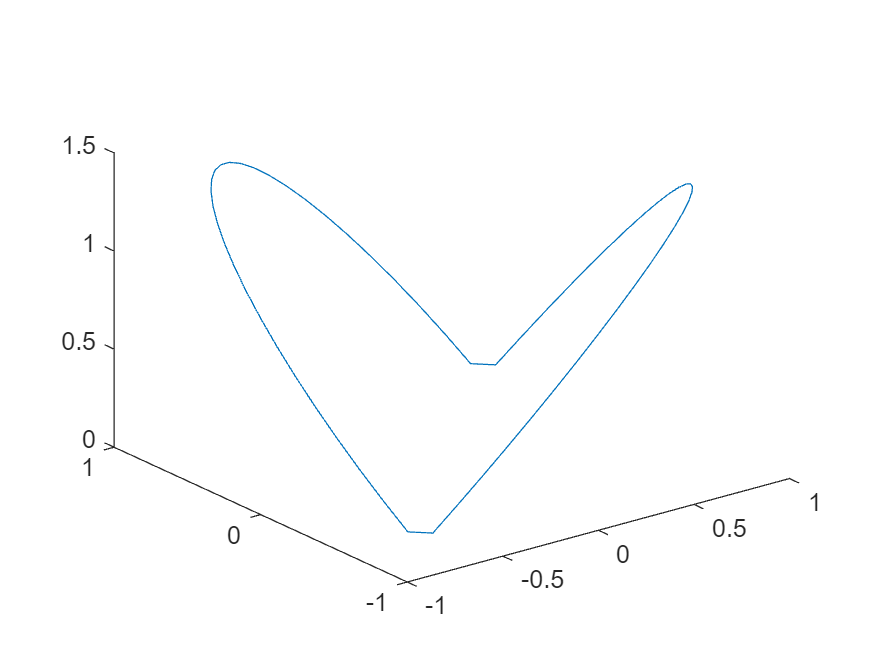


plot3(x,y,z)

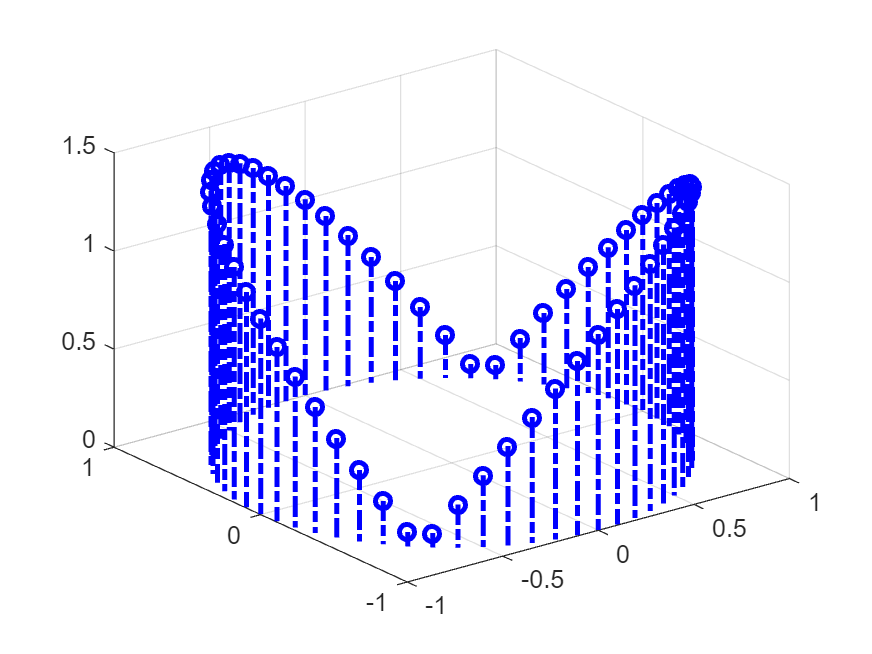

stem3(x,y,z,'bo-.','LineWidth',2)

Scatter3

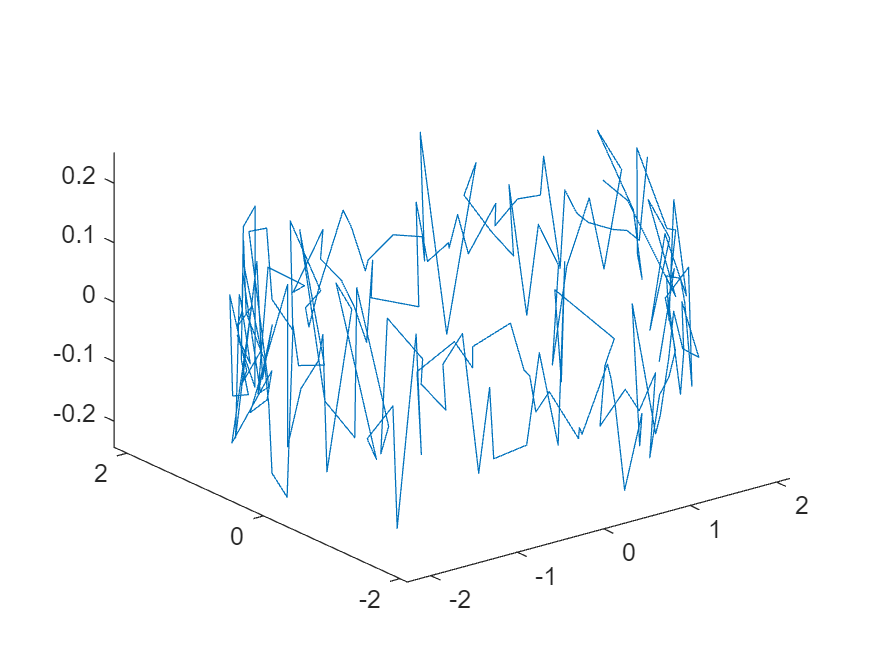

t = linspace(0,4*pi,200);
x = 2*cos(t)+0.1*randn(size(t));
y = 2*sin(t)+0.1*randn(size(t));
z = 0.1*randn(size(t));

plot3(x,y,z)

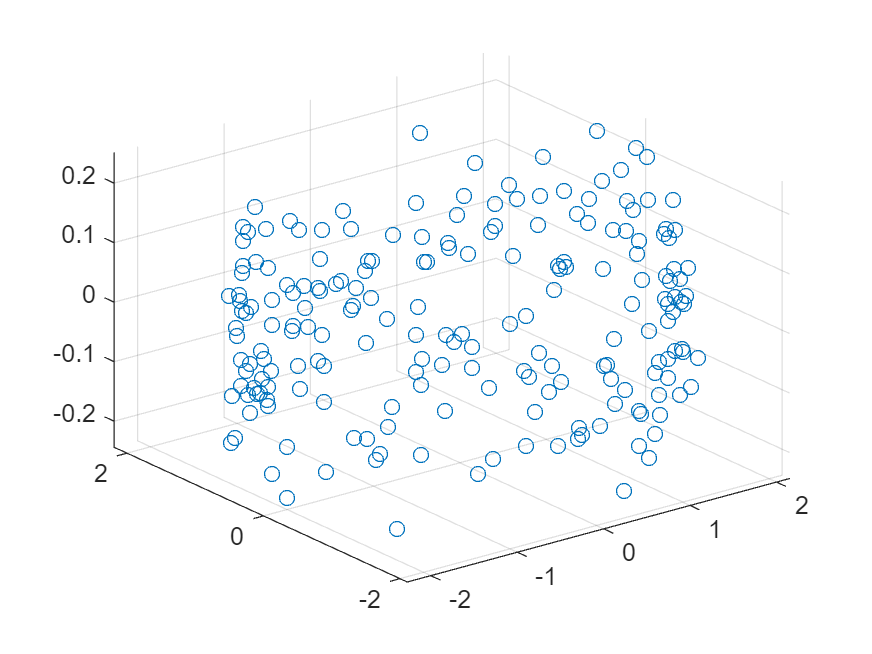


scatter3(x,y,z)
view(2)
view(3)

Contour Plots

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


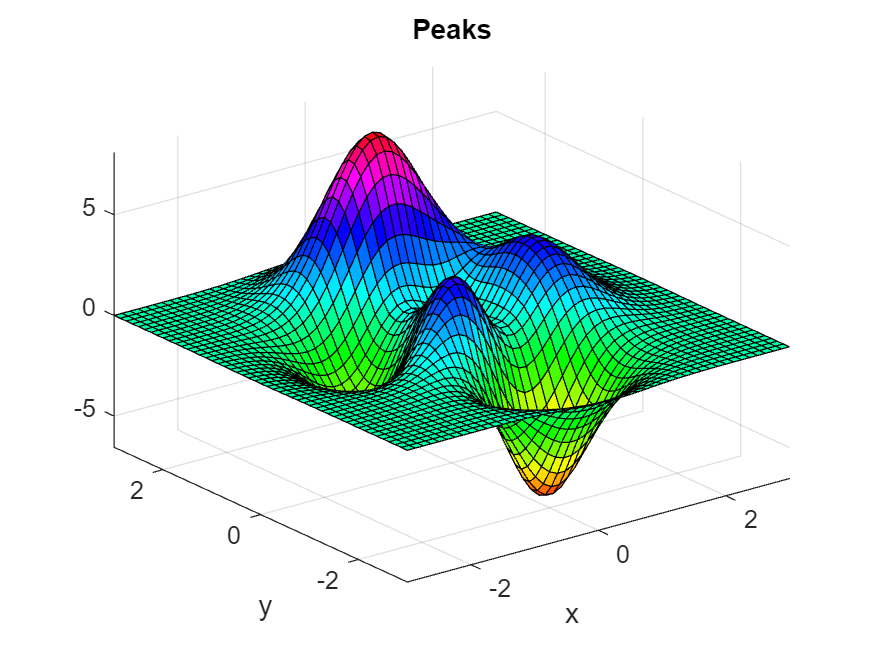

%doc peaks
peaks

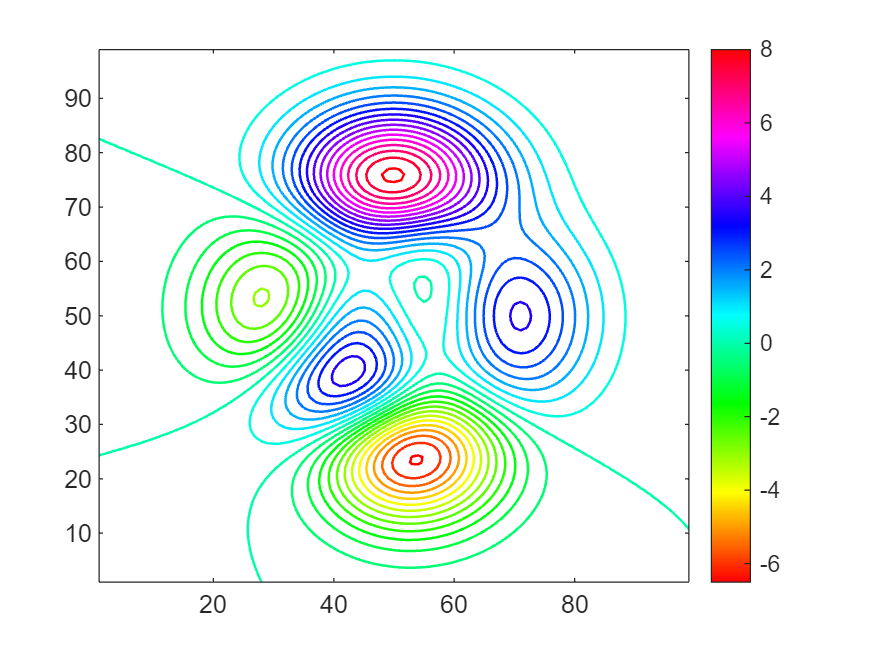

z = peaks(99);

contour(z,'LineWidth',1,'LevelStep',0.5)
colormap hsv
colorbar

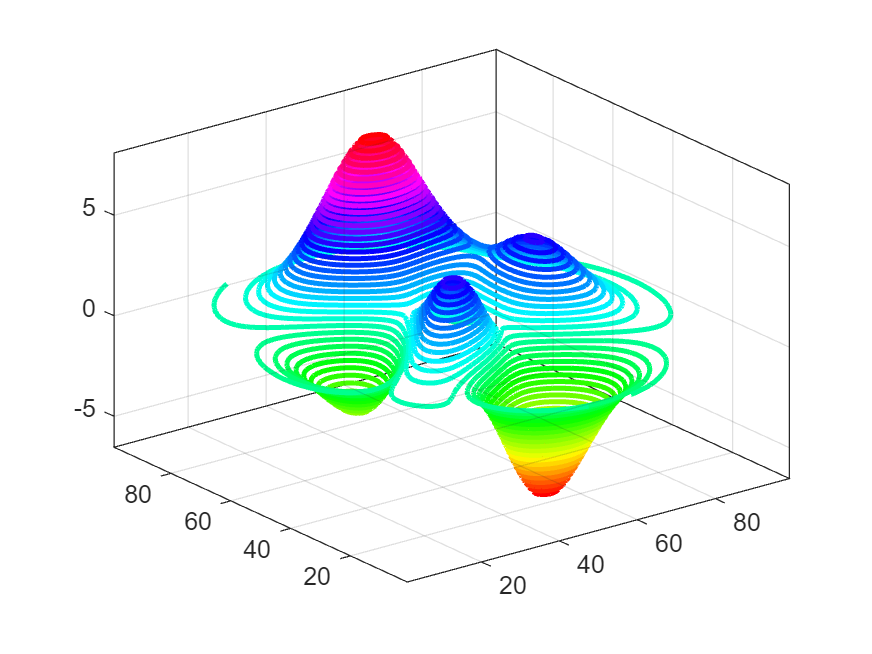


contour3(z,50,'LineWidth',2)

Surface and Mesh Plots

x = [1 2 3];
y = [1 2 3 4]';


X = repmat(x, size(y,1),1)

X =      1     2     3
     1     2     3
     1     2     3
     1     2     3


Y = repmat(y, 1, size(x,2))

Y =      1     1     1
     2     2     2
     3     3     3
     4     4     4



Z = sqrt(X.^2+Y.^2)

Z =     1.4142    2.2361    3.1623
    2.2361    2.8284    3.6056
    3.1623    3.6056    4.2426
    4.1231    4.4721    5.0000


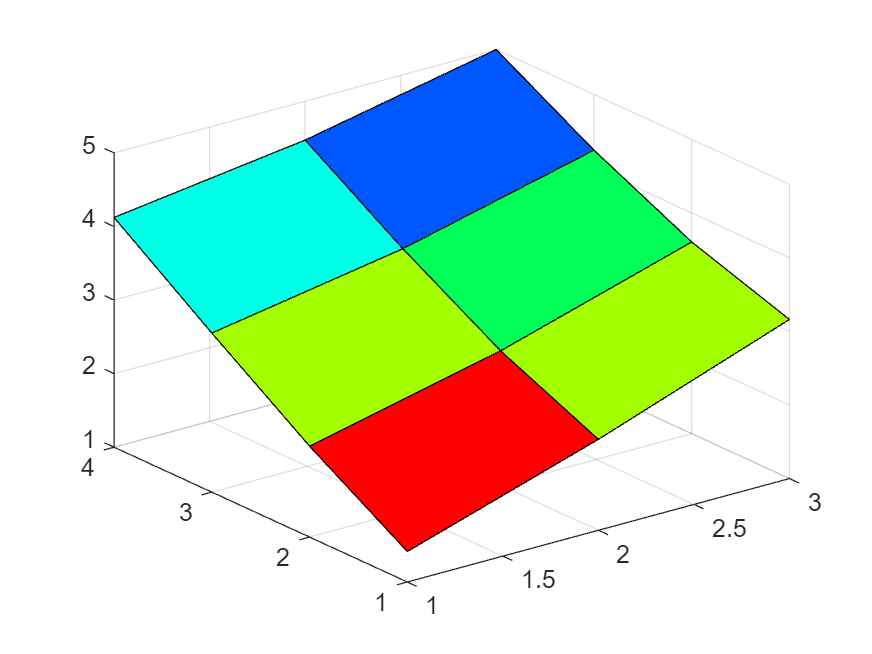


surf(X,Y,Z)

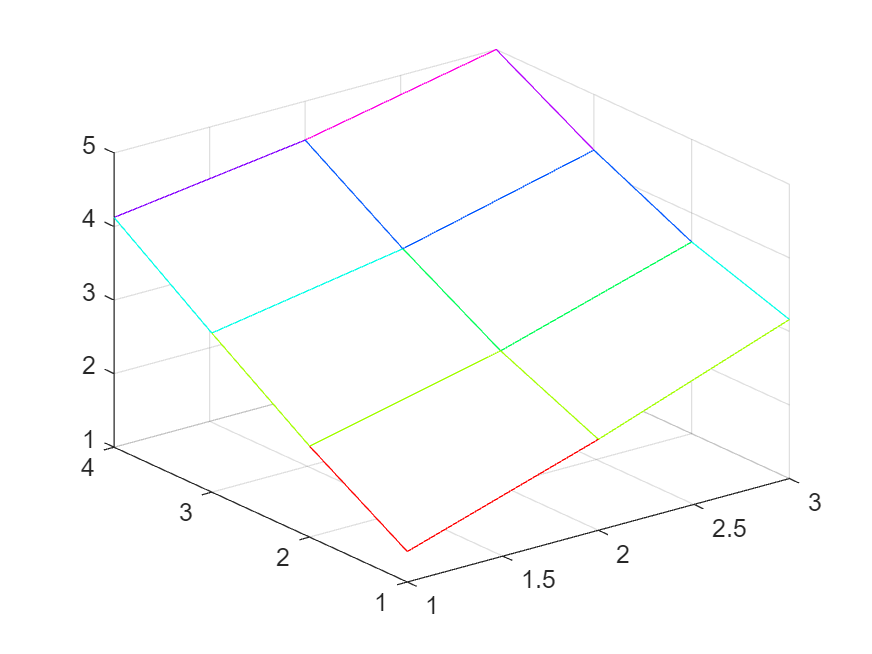

mesh(X,Y,Z)

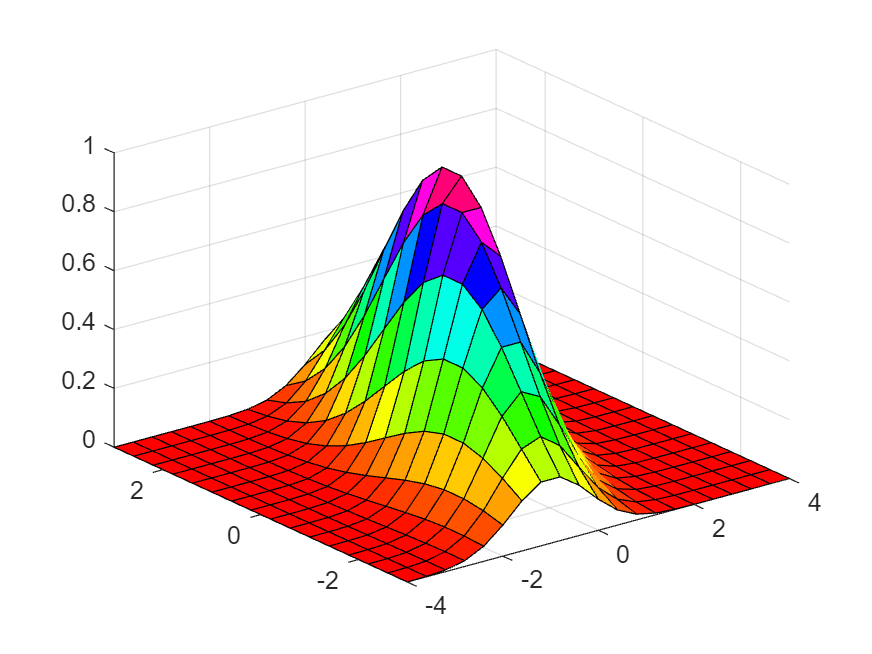

x = -4:0.4:4;
y = -3:0.4:3;

[X, Y] = meshgrid(x,y);

Z = exp(-0.5*(X.^2+0.5*(X-Y).^2));

surf(X,Y,Z)

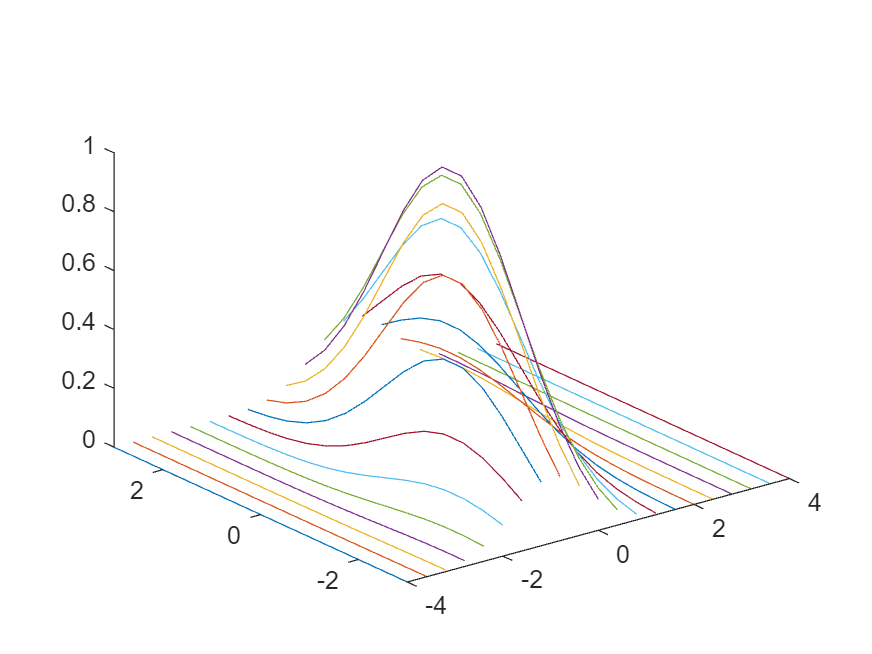


plot3(X,Y,Z)

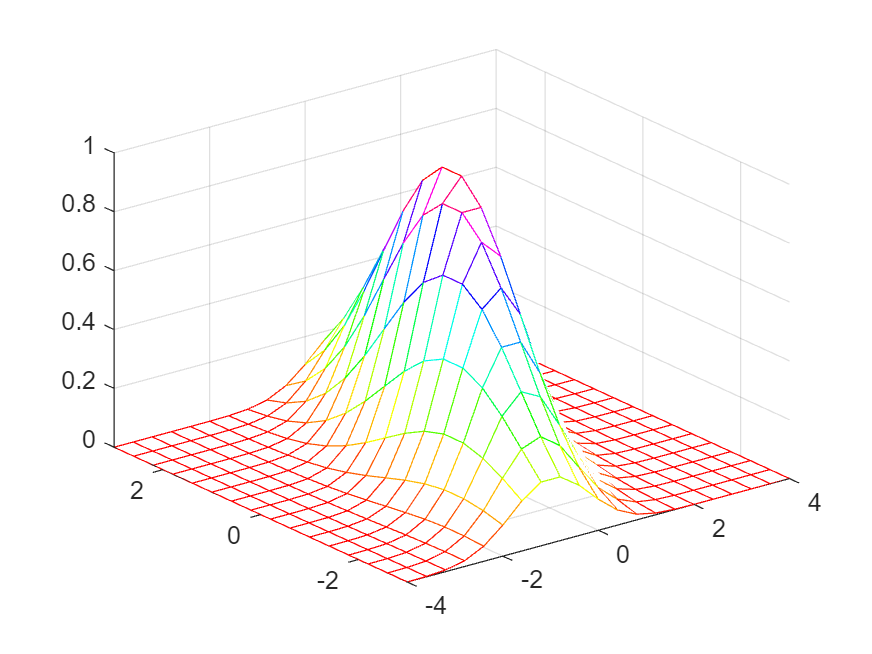


mesh(X,Y,Z)

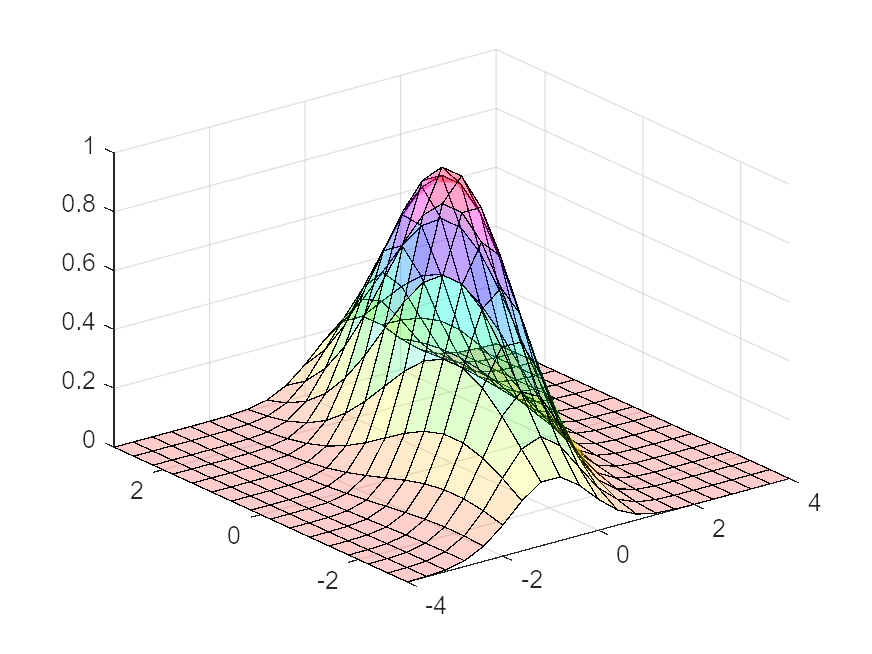


surf(X,Y,Z)
alpha(0.2)


surf(x,y,Z)

mesh(x,y,Z)

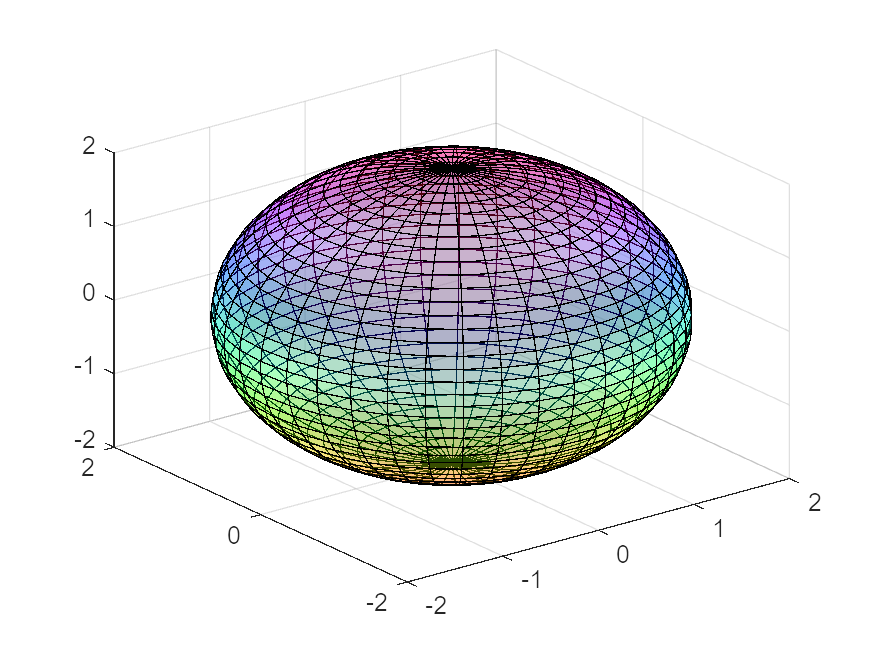

n = 40;
r = 2;
theta = linspace(-pi,pi,n);
phi = linspace(-pi/2,pi/2,n);

[THETA, PHI] = meshgrid(theta,phi);

x = r.*cos(PHI).*cos(THETA);
y = r.*cos(PHI).*sin(THETA);
z = r.*sin(PHI);

surf(x,y,z)
alpha(0.3)

Ribbon Plots

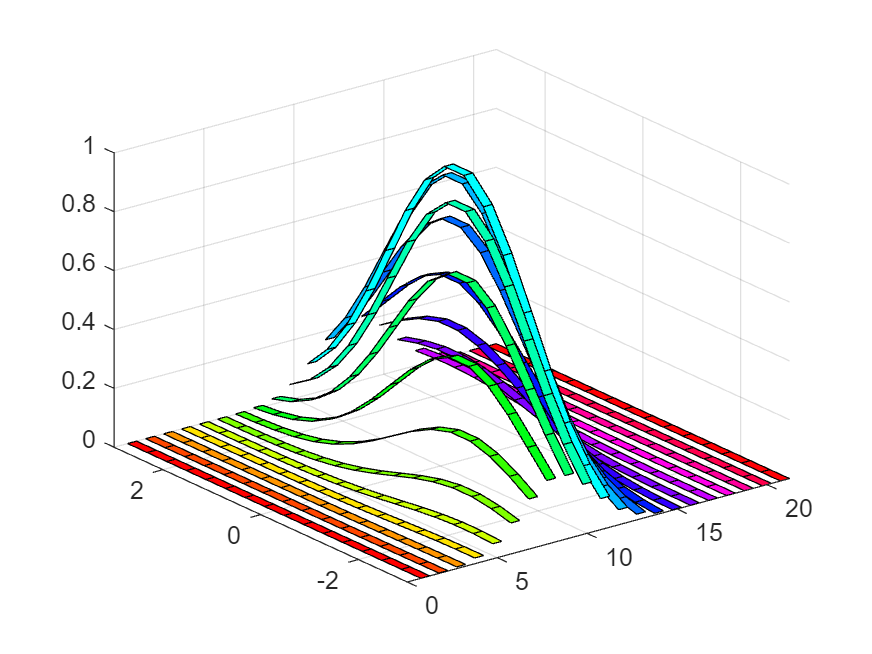

x = -4:0.4:4;
y = -3:0.4:3;

[X, Y] = meshgrid(x,y);

Z = exp(-0.5*(X.^2+0.5*(X-Y).^2));
%doc ribbon
ribbon(Y,Z,0.5)

Pcolor

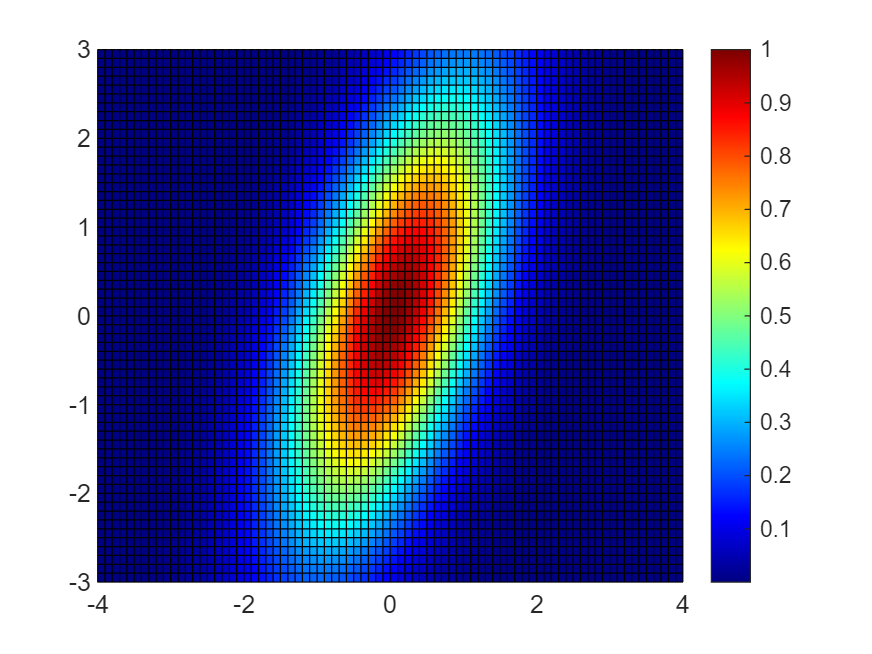

x = -4:0.1:4;
y = -3:0.1:3;

[X, Y] = meshgrid(x,y);

Z = exp(-0.5*(X.^2+0.5*(X-Y).^2));
%doc pcolor
pcolor(X,Y,Z)
colormap jet
colorbar